# Sessão 1 – 1.5 - Secções Biquadráticas com 3 Amplificadores Operacionais

## 1.1 Objectivos

clear;

## 1.2 Equipamento para Ensaio Laboratorial

% Resistor values (Ohm)
R1 = 51e3;
R2 = 100e3;
R3 = 10e3;
R4 = 10e3;
R5 = 100e3;
R6 = 10e3;
R7 = 1e6;
R8 = 100e3;
R9 = 51e3;
R10 = 100e3;
R11 = 10e3;

% Potentiometer values (Ohm) 
P1 = 100e3; % (LOG)
P2 = 10e3; %(LIN)

% Capacitor values (F)
C1 = 4.7e-9;
C2 = 4.7e-9;

% Ampops = 741

## 1.3 Procedimento Experimental

Vin = 12; %(V)
Vin_ = -12; %(V)

## 1.5 Secção Biquadrática de Kerwin, Huelsman e Newcom (KHN)		

## 1.5.1 / 1.5.2

Transfer functions are given by:

$T_1(s) = \frac{V_1(s)}{V_i(s)} =\frac{Ks^2}{s^2+(\omega_0/Q)s+\omega_0^2}$ (HP)

$T_2(s) = \frac{V_2(s)}{V_i(s)} =\frac{-K\omega_0 s}{s^2+(\omega_0/Q)s+\omega_0^2}$ (BP)

$T_3(s) = \frac{V_3(s)}{V_i(s)} =\frac{K\omega_0^2}{s^2+(\omega_0/Q)s+\omega_0^2}$ (LP)

Circuito subtractor: $V_o(s)=-\frac{R_4}{R_1}V_1(s) +\left(1+\frac{R_4}{R_1}\right)\frac{R_3}{R_2+R_3}V_2(s)$

Circuito somador-inversor: $V_o(s)= -\frac{R_3}{R_1}V_1(s) -\frac{R_3}{R_2}V_2(s) $

Circuito multiplicador-inversor: $\frac{V_o(s)}{V_i(s)} = -\frac{R_2}{R_1}$

Circuito integrador inversor: $\frac{V_o(s)}{V_i(s)} = -\frac{1}{RCs}$

Por combinação dos circuitos acima (teorema da sobreposição) vem

$V_2(s) = -\frac{1}{R_6C_1}V_1(s) = -\frac{\omega_0}{s}V_1(s)$,

$V_3(s) = -\frac{1}{R_{11}C_2}V_2(s) = -\frac{\omega_0}{s}V_2(s)$,

logo

$\omega_0 = \frac{1}{R_6C_1}= \frac{1}{R_{11}C_2}$.

omega_0 = 1/(R6*C1); % = 1/(R11*C2);

Para além disso,


$$V_1(s) =\frac{P_2}{R_3+P_2}\left(1+\frac{R_5}{R_2}\right) V_i(s) + \frac{R_3}{R_3+P_2}\left(1+\frac{R_5}{R_2}\right) V_2(s)  -\frac{R_5}{R_2}V_3(s)= K V_i(s) +\frac{1}{Q}V_2(s)- V_3(s)$$


logo


$$K=\frac{P_2}{R_3+P_2}\left(1+\frac{R_5}{R_2}\right)$$



$$-\frac{R_5}{R_2} = -1 \Rightarrow R_5 = R_2$$



$$\frac{1}{Q}=\frac{R_3}{R_3+P_2}\left(1+\frac{R_5}{R_2}\right) \Rightarrow Q = \frac{R_3+P_2}{R_3\left(1+\frac{R_5}{R_2}\right)}$$


K = (P2/(P2+R3))*(1+R5/R2);
Q = (R3+P2)/(R3*(1+R5/R2));
% R2 == R5 = true
fprintf("omega_0 = %g rad/s | K = %g | Q = %g\n",omega_0,K,Q);

omega_0 = 21276.6 rad/s | K = 1 | Q = 1


Transfer functions are then given by 

s = tf('s');
T1 = zpk(K*s^2/(s^2+(omega_0/Q)*s+omega_0^2))


T1 =
 
              s^2
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



T2 = zpk(-K*s*omega_0/(s^2+(omega_0/Q)*s+omega_0^2))


T2 =
 
            -21277 s
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



T3 = zpk(K*omega_0^2/(s^2+(omega_0/Q)*s+omega_0^2))


T3 =
 
           4.5269e+08
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



## 1.5.3

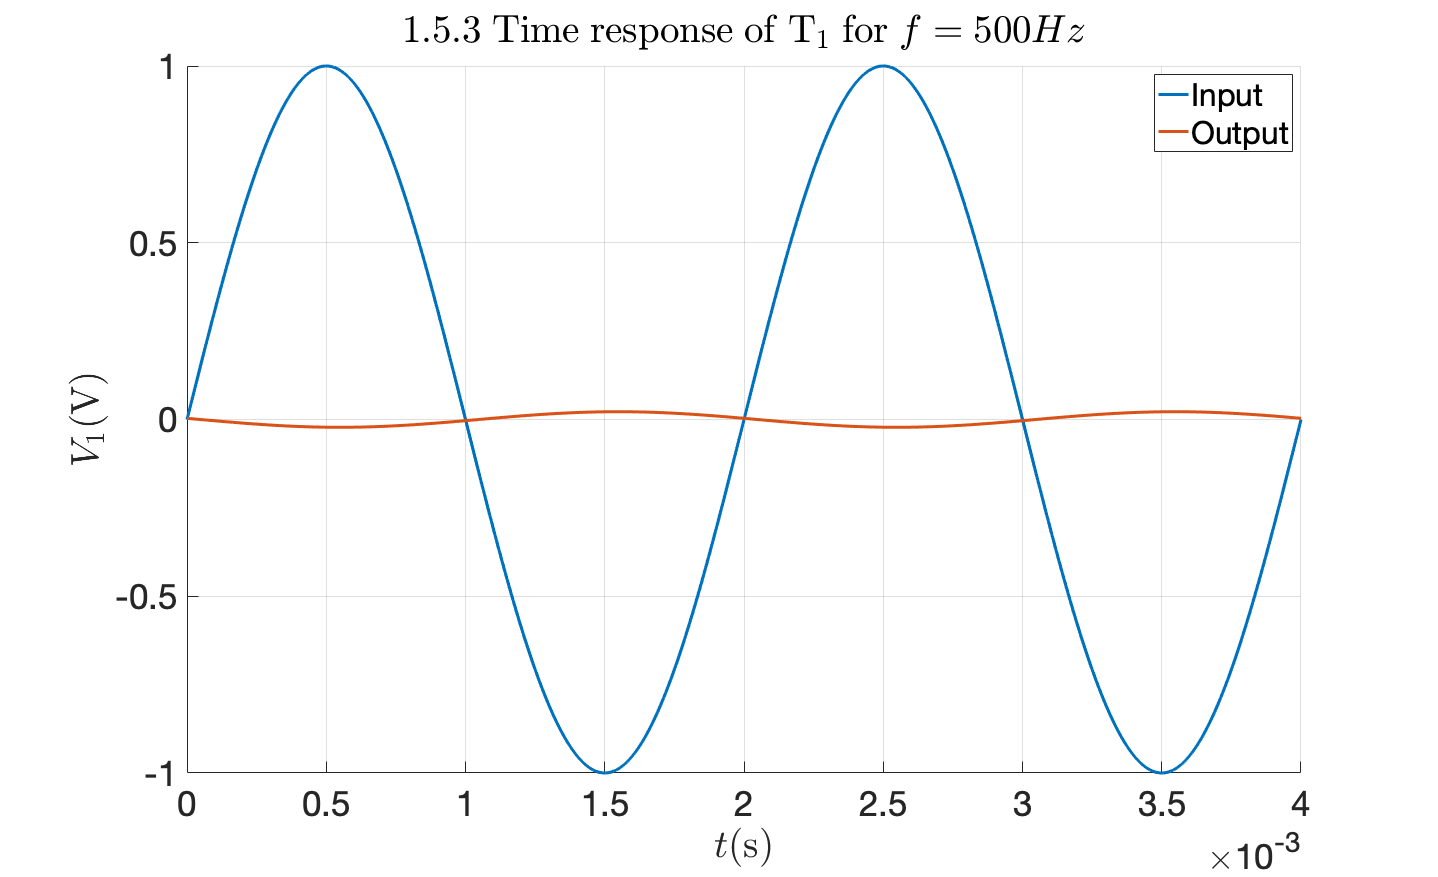

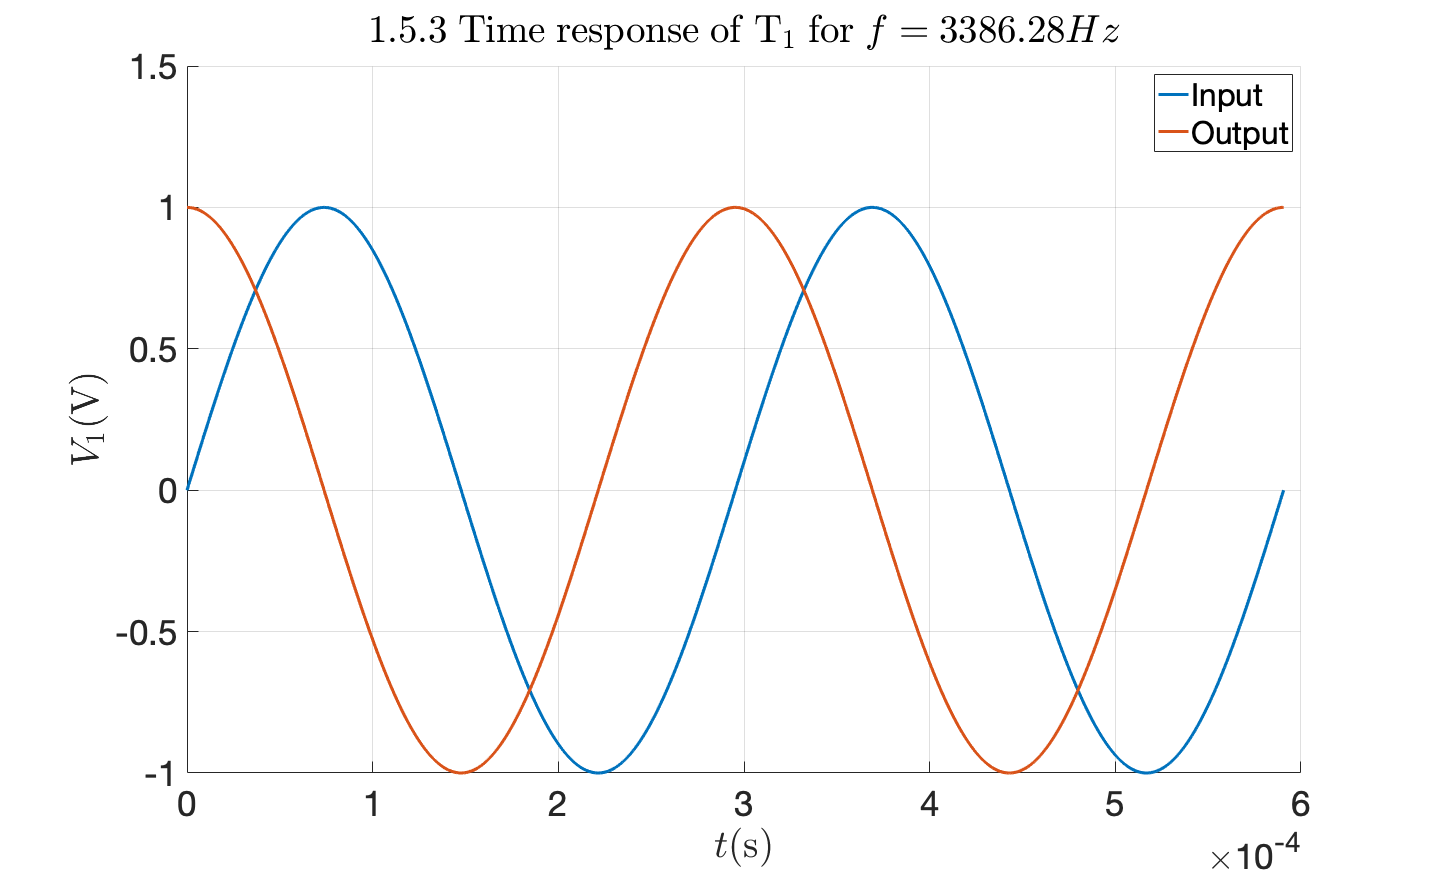

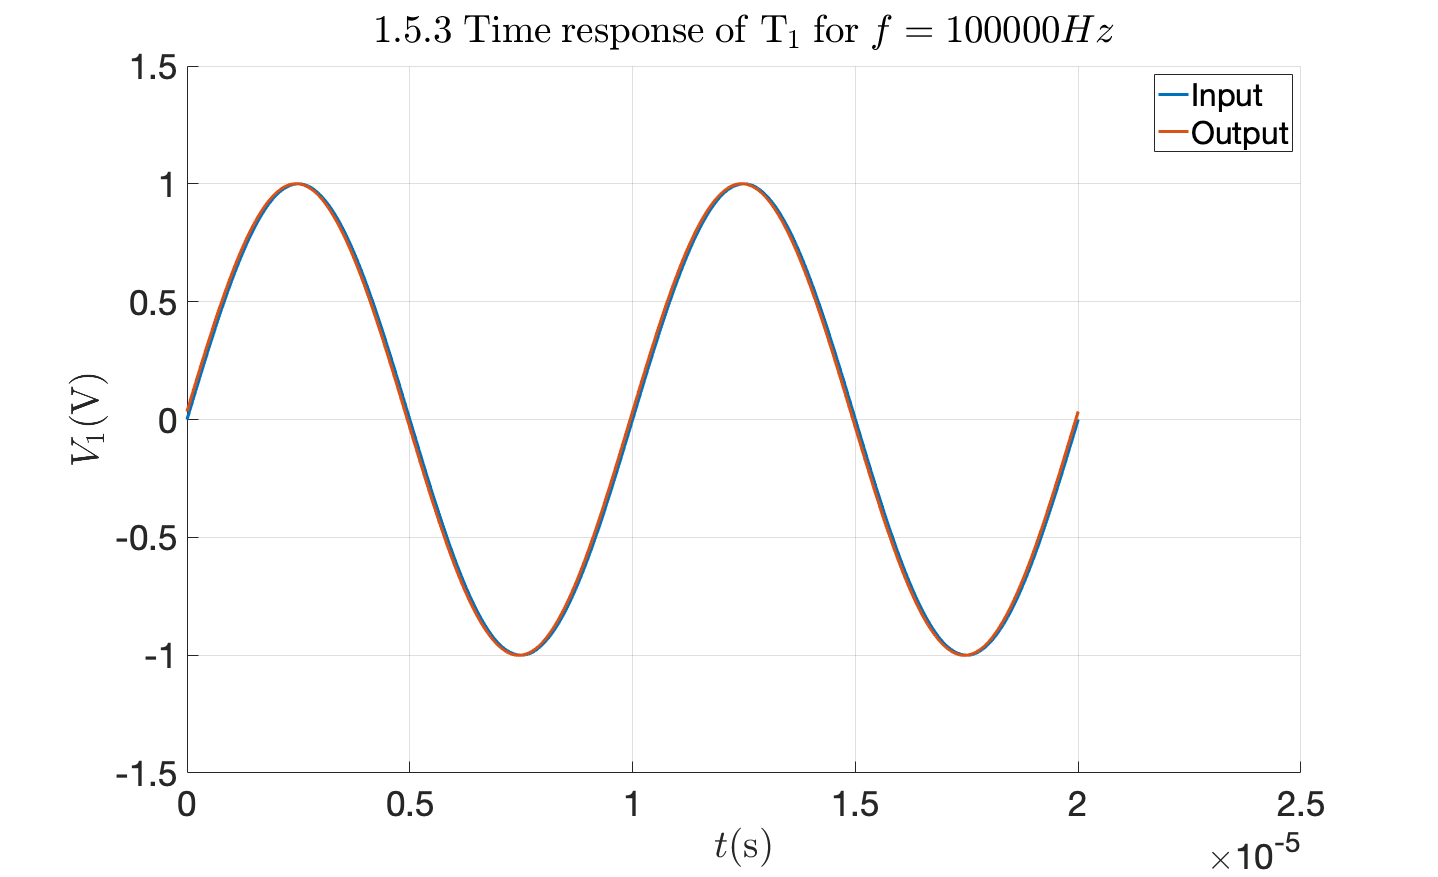

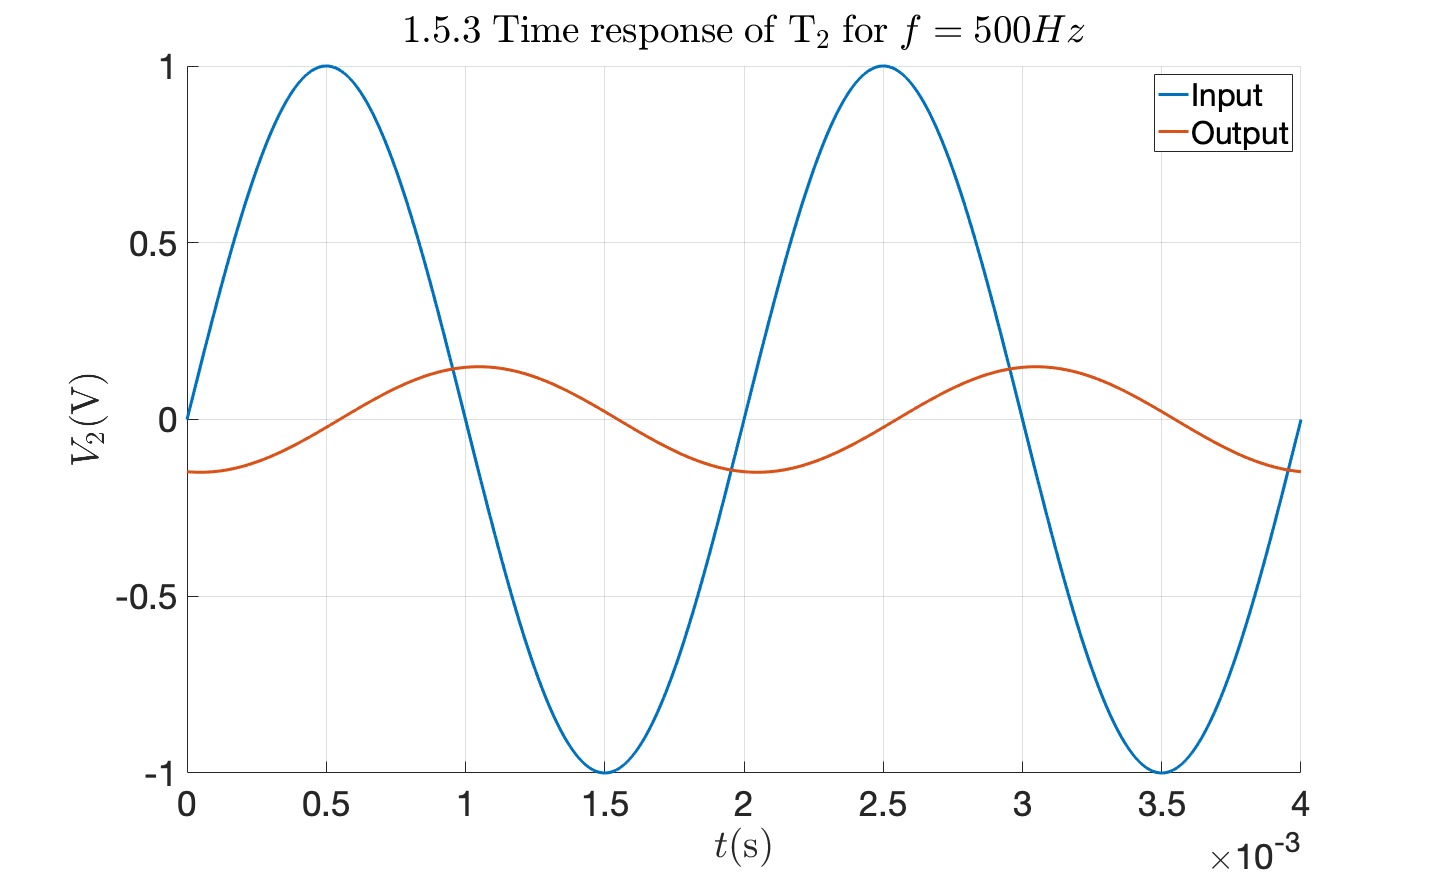

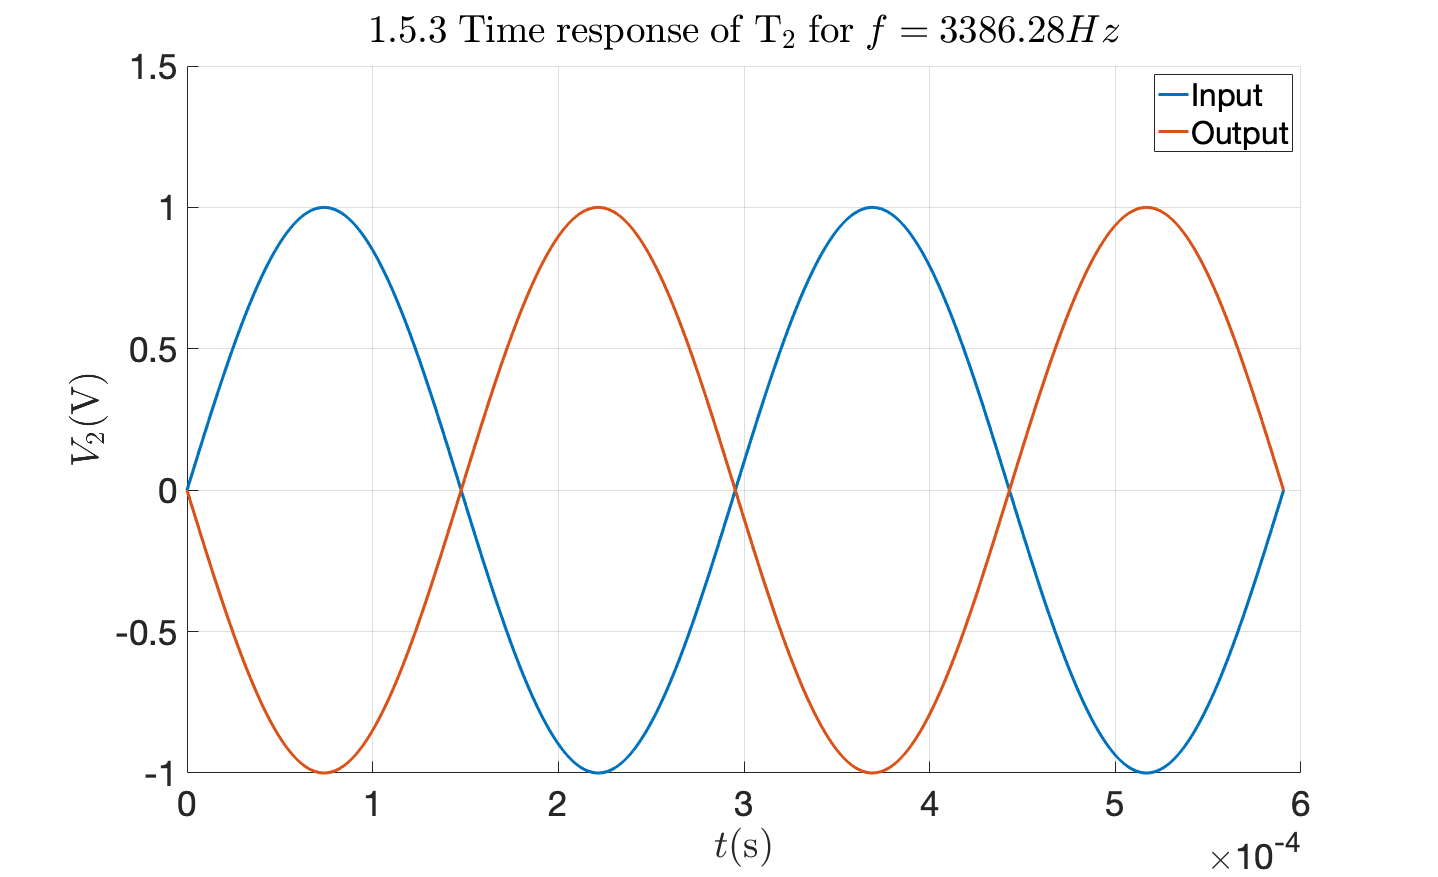

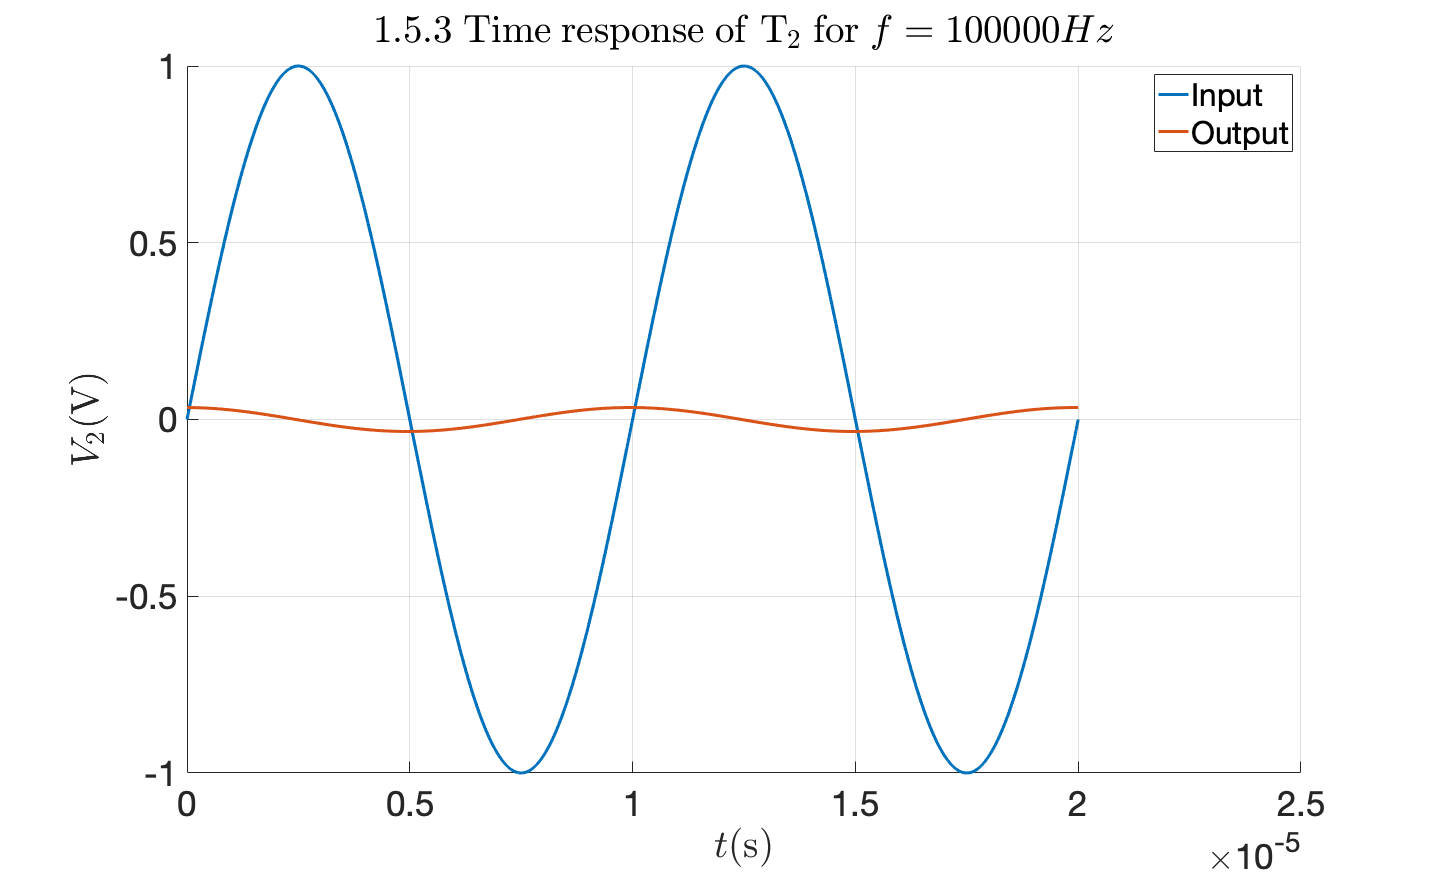

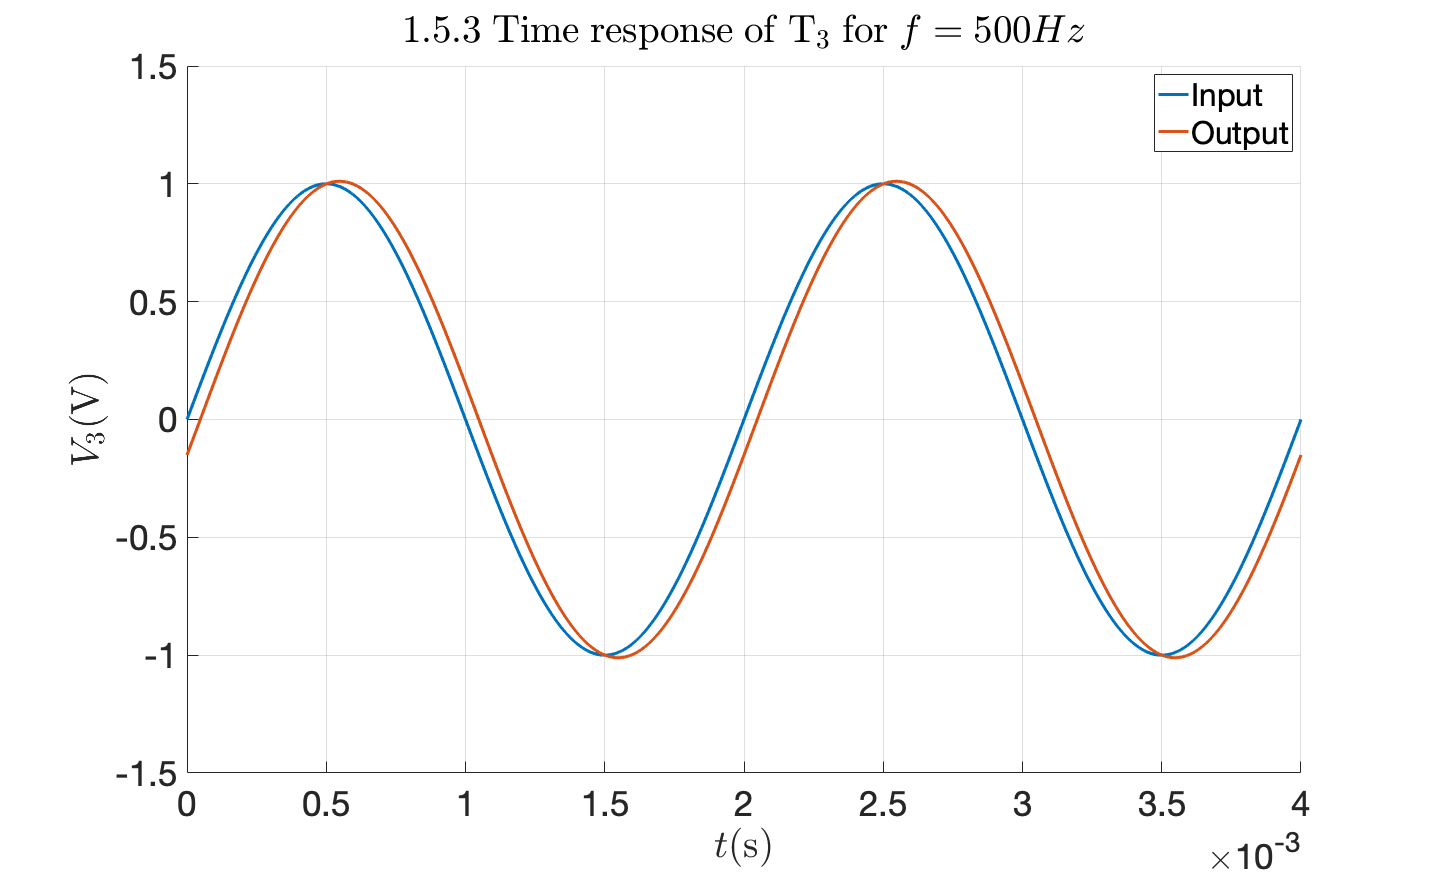

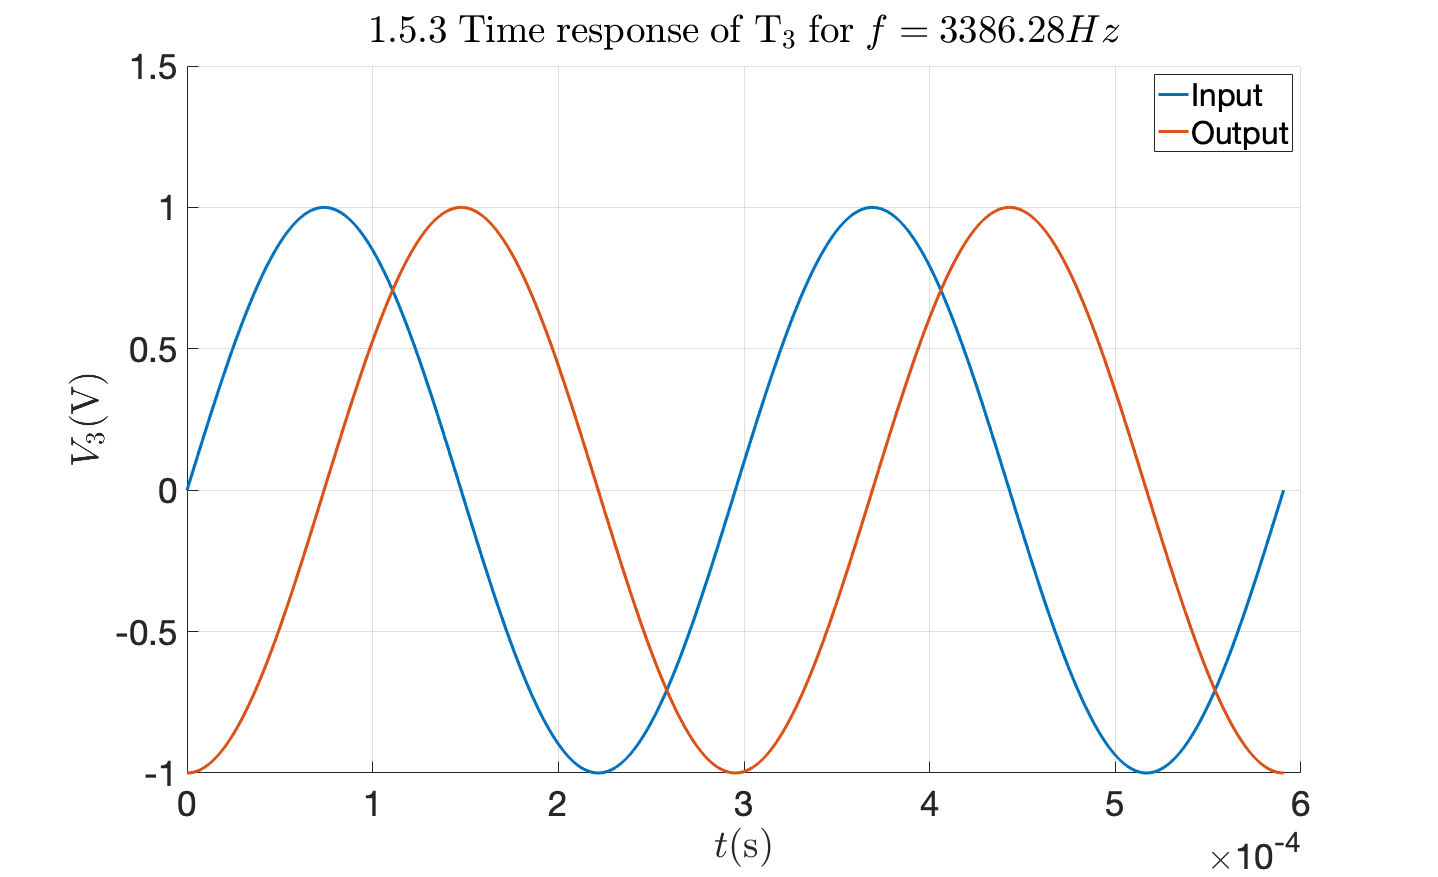

f = [500 omega_0/(2*pi) 100e3]; % (Hz)
for filter = 1:3
    for freqN = 1:3
        t = 0:2/(1000*f(freqN)):2/f(freqN);
        in = sin(2*pi*f(freqN)*t);
        if filter == 1
            resp = freqresp(T1,2*pi*f(freqN));
        elseif filter == 2
            resp = freqresp(T2,2*pi*f(freqN));
        else
            resp = freqresp(T3,2*pi*f(freqN));
        end
        
        out = abs(resp)*sin(2*pi*f(freqN)*t+angle(resp));
        figure('units','normalized','outerposition',[0 0 1 1]);
        hold on;
        set(gca,'FontSize',35);
        ax = gca;
        ax.XGrid = 'on';
        ax.YGrid = 'on';
        title(strcat('$1.5.3\; \mathrm{Time\;response\;of}\;\mathrm{T}_',sprintf('%d',filter),'\;\mathrm{for}\;f =',sprintf('%g Hz$',f(freqN))),'Interpreter','latex');
        plot(t,in,'LineWidth',3);
        plot(t,out,'LineWidth',3);
        legend('Input','Output');
        ylabel(strcat(sprintf('$V_%d',filter),'\mathrm{(V)}$'),'Interpreter','latex');
        xlabel('$t \mathrm{(s)}$','Interpreter','latex');
        saveas(gcf,sprintf('./Session1DATA/timeResponseFilter%dFreqN%d.fig',filter,freqN));
        saveas(gcf,sprintf('./Session1DATA/timeResponseFilter%dFreqN%d.png',filter,freqN));
        hold off;  
    end
end

## 1.5.4

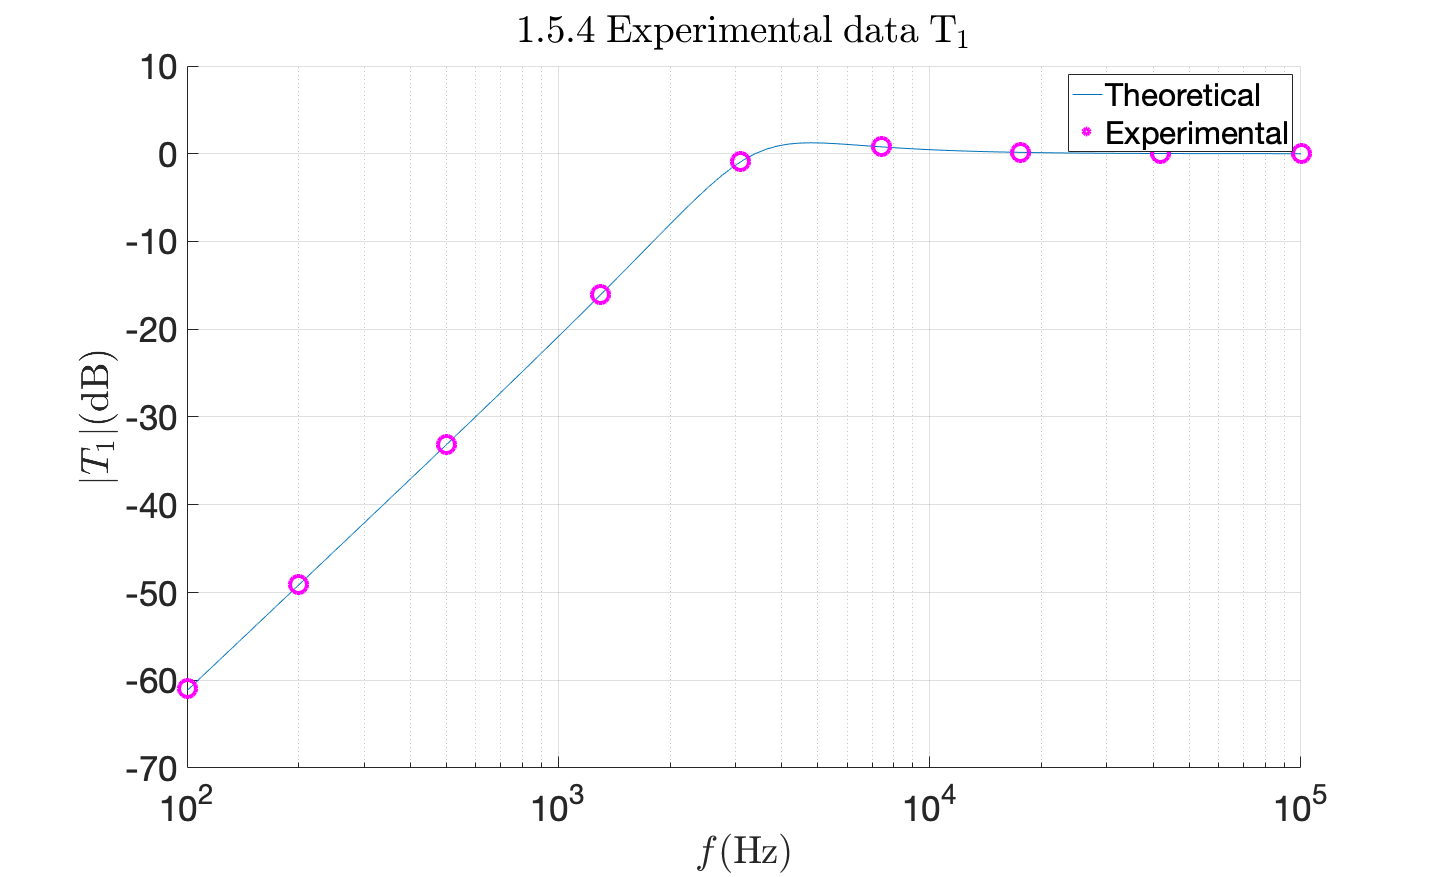

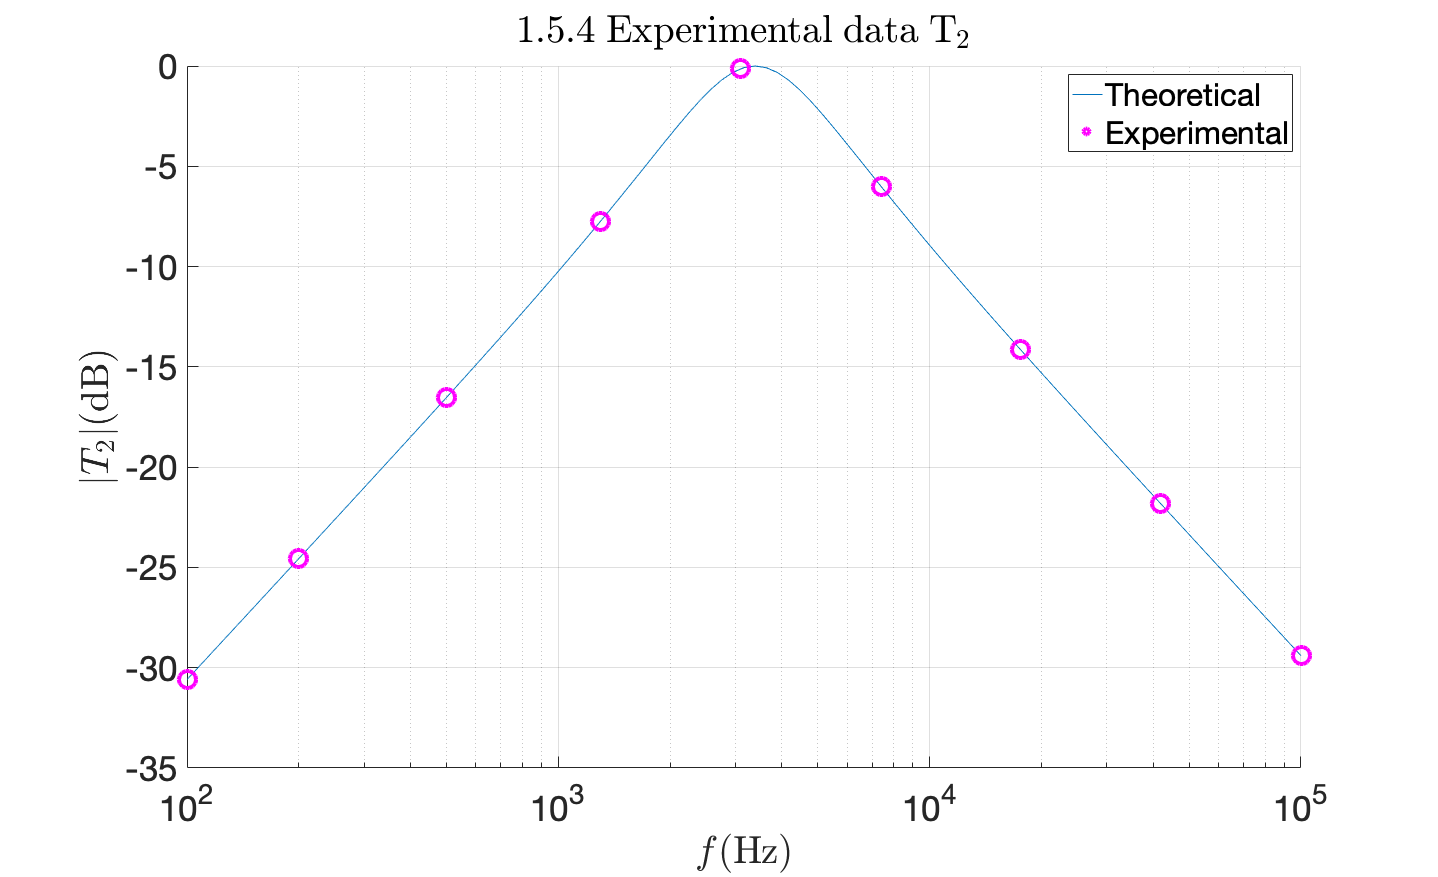

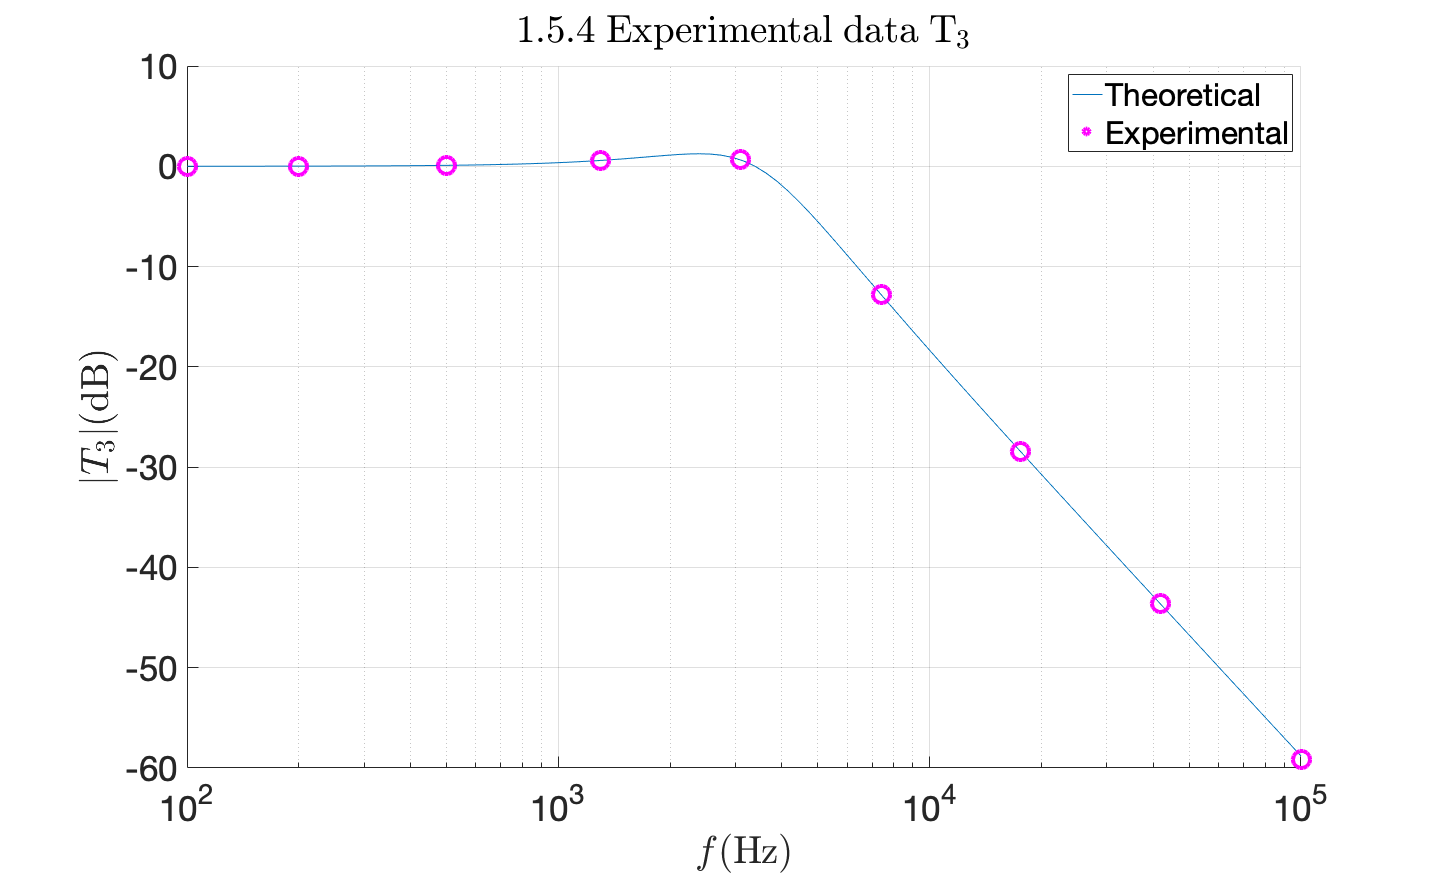

fLog = log10(100):(log10(100e3)-log10(100))/100:log10(100e3);
f = 10.^fLog;
gainBode = zeros(3,length(f));
for i = 1:length(f)
    gainBode(1,i) = 20*log10(abs(freqresp(T1,2*pi*f(i))));
    gainBode(2,i) = 20*log10(abs(freqresp(T2,2*pi*f(i))));
    gainBode(3,i) = 20*log10(abs(freqresp(T3,2*pi*f(i))));
end

% Amostragem uniforme
% fLogExp = 1.6:(log10(100e3)-1.6)/9:log10(100e3);
% fExp = round((10.^fLogExp)/100)*100;
% gainBodeExp = zeros(3,length(fExp));
% for freqN = 1:length(fExp)
%     gainBodeExp(1,freqN) = abs(freqresp(T1,2*pi*fExp(freqN)));
%     gainBodeExp(2,freqN) = abs(freqresp(T2,2*pi*fExp(freqN)));
%     gainBodeExp(3,freqN) = abs(freqresp(T3,2*pi*fExp(freqN)));
% end
% VoutExp = VAmp*gainBodeExp;
% gainBodeExp = 20*log10(abs(gainBodeExp));


% Experimental data
VAmp = 1; %(V)
dataExp = importdata('./Session1Exp/1_5_4_exp.txt');
fExp = dataExp(:,1)';
VExp = dataExp(:,2:4)';
gainBodeExp = 20*log10(abs(VExp/VAmp));

for filter = 1:3
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    title(strcat('$1.5.4\; \mathrm{Experimental\;data}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
    plot(f,gainBode(filter,:))
    scatter(fExp,gainBodeExp(filter,:),300,'o','magenta','LineWidth',4);
    legend('Theoretical','Experimental');
    set(gca,'xscale','log')
    ylabel(strcat(sprintf('$|T_%d|',filter),'\mathrm{(dB)}$'),'Interpreter','latex');
    xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
    saveas(gcf,sprintf('./Session1DATA/bodeExperimental%d.fig',filter));
    saveas(gcf,sprintf('./Session1DATA/bodeExperimental%d.png',filter));
    hold off; 
end

## 1.5.5

k: com ganho estático no passa baixo

ordem: com -20 dB/dec nos ramos em que desce assitoticamente

Achar Q e w0 faz se regressão?

k pelo passa baixo

Ou faz-se regressao a tudo e pronto!! (mais vale)

## 1.5.6

Agora que o potenciómetro é ligado à massa:

$R_v+R_g = P_2$.

Temos, portanto,


$$V_1(s) =\frac{R_v||R_g}{R_3+R_v||R_g}\left(1+\frac{R_5}{R_2}\right) V_i(s) + \frac{R_3||R_g}{R_3||R_g+P_2}\left(1+\frac{R_5}{R_2}\right) V_2(s)  -\frac{R_5}{R_2}V_3(s)\\
=\frac{(P_2-R_g)R_g}{R_3P_2+(P_2-R_g)R_g}\left(1+\frac{R_5}{R_2}\right) V_i(s) + \frac{R_3||R_g}{R_3||R_g+P_2}\left(1+\frac{R_5}{R_2}\right) V_2(s)  -\frac{R_5}{R_2}V_3(s)\\
= K V_i(s) +\frac{1}{Q}V_2(s)- V_3(s)$$


logo


$$K=\frac{(P_2-R_g)R_g}{R_3P_2+(P_2-R_g)R_g}\left(1+\frac{R_5}{R_2}\right) $$



$$-\frac{R_5}{R_2} = -1 \Rightarrow R_5 = R_2$$



$$\frac{1}{Q}= \frac{R_3||R_g}{R_3||R_g+P_2}\left(1+\frac{R_5}{R_2}\right) \Rightarrow Q = \frac{R_3||R_g+P_2}{(R_3||R_g)\left(1+\frac{R_5}{R_2}\right)}$$


$\omega_0$ está dependente dos dois integradores-inversores (integradores de Miller) que permanecem inalterados, pelo que $\omega_0 = \frac{1}{R_6C_1}= \frac{1}{R_{11}C_2}$, permanece inalterado.

Rg = P2*[0:0.1:0.5] % (Ohm) 

Rg =            0        1000        2000        3000        4000        5000


K_ = (1+R5/R2)*(P2-Rg).*Rg./(P2*R3+(P2-Rg).*Rg)

K_ =          0    0.1651    0.2759    0.3471    0.3871    0.4000


Q_ = (1./(1/R3+1./Rg)+P2)./(1./(1/R3+1./Rg).*(1+R5/R2)) 

Q_ =        Inf    6.0000    3.5000    2.6667    2.2500    2.0000


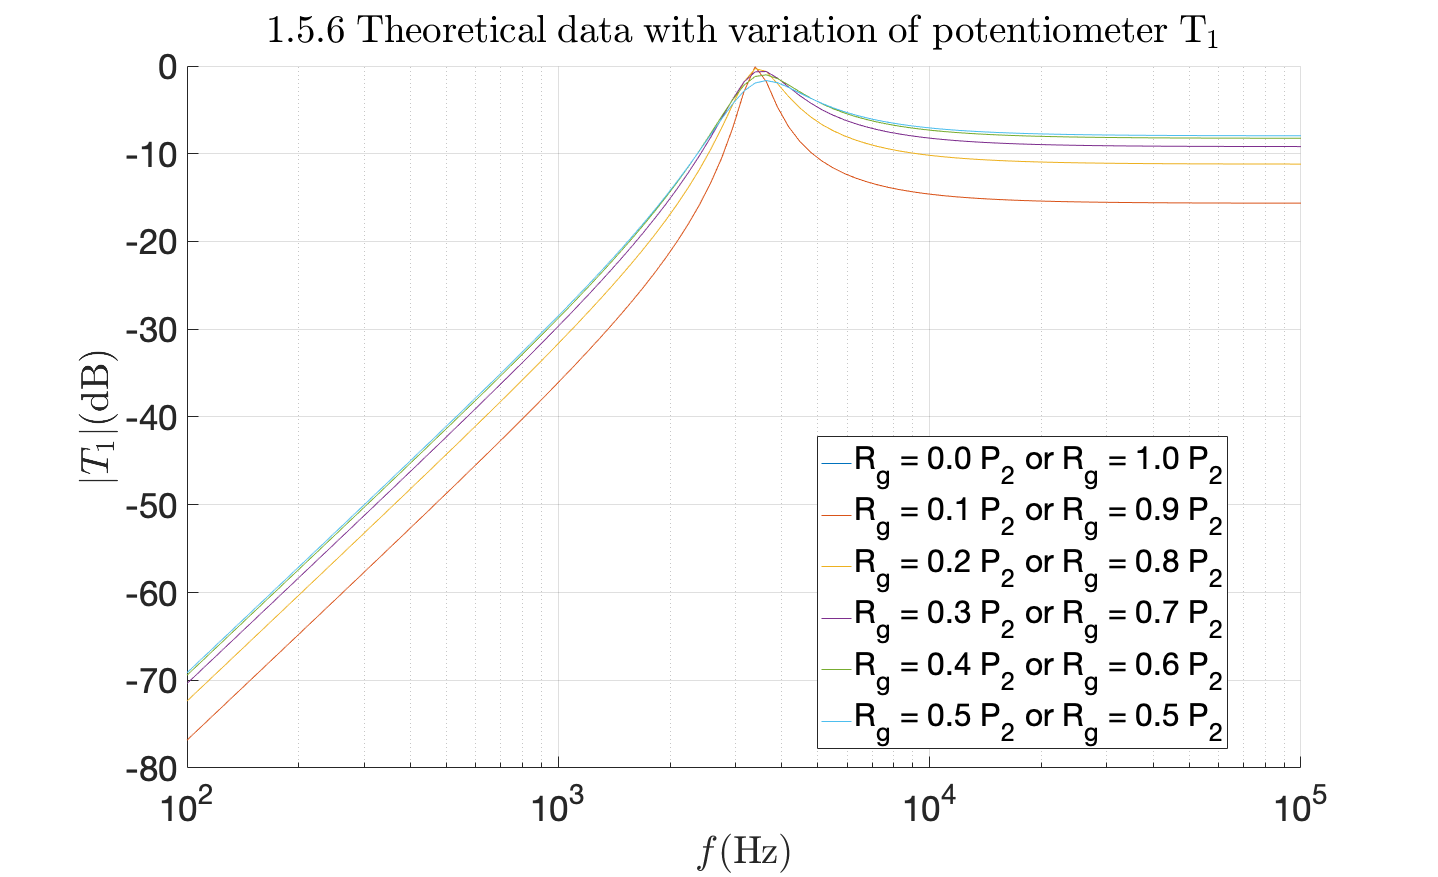

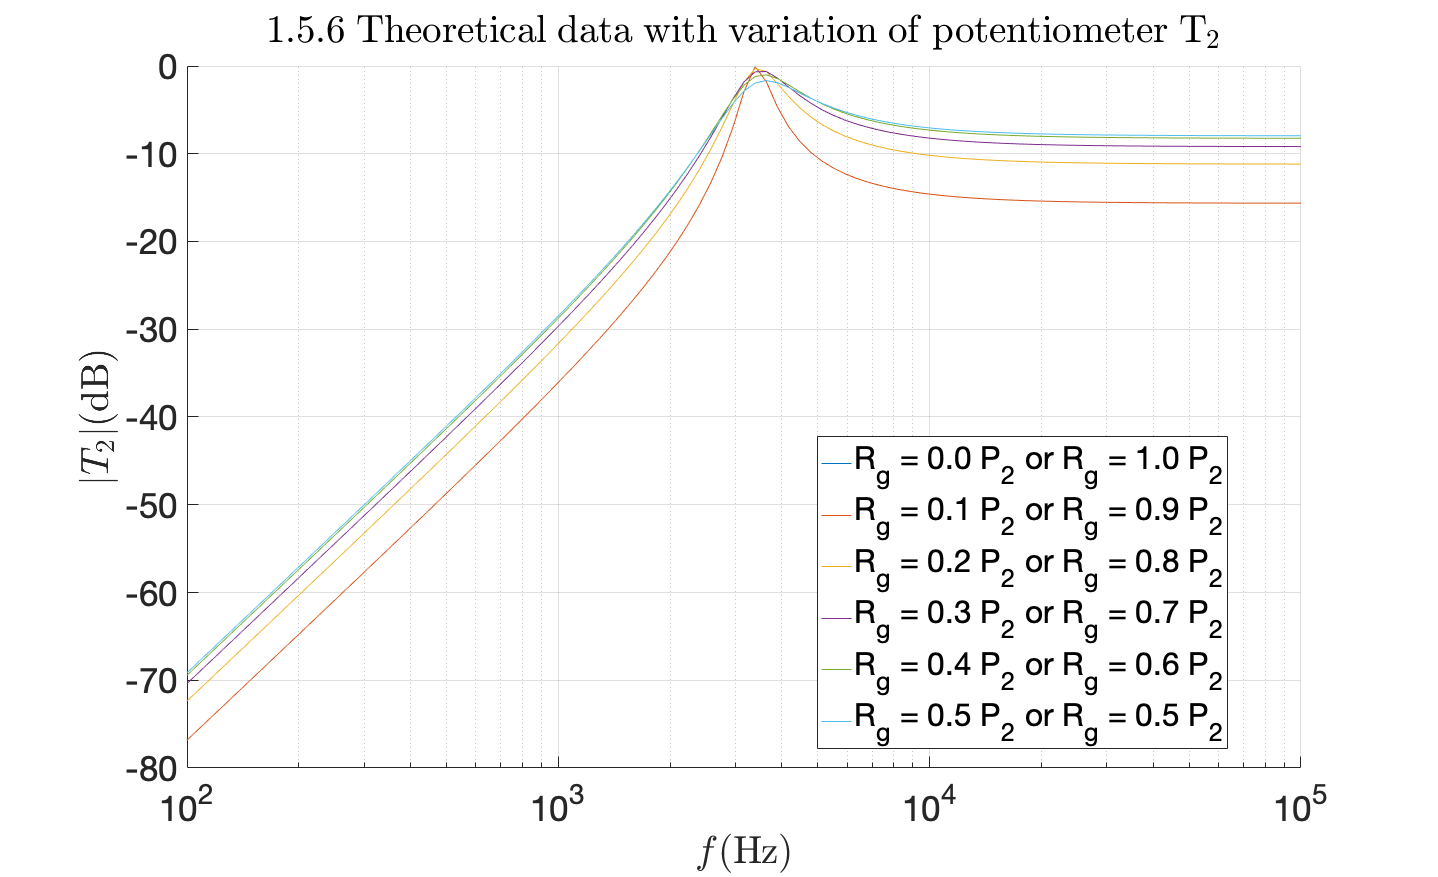

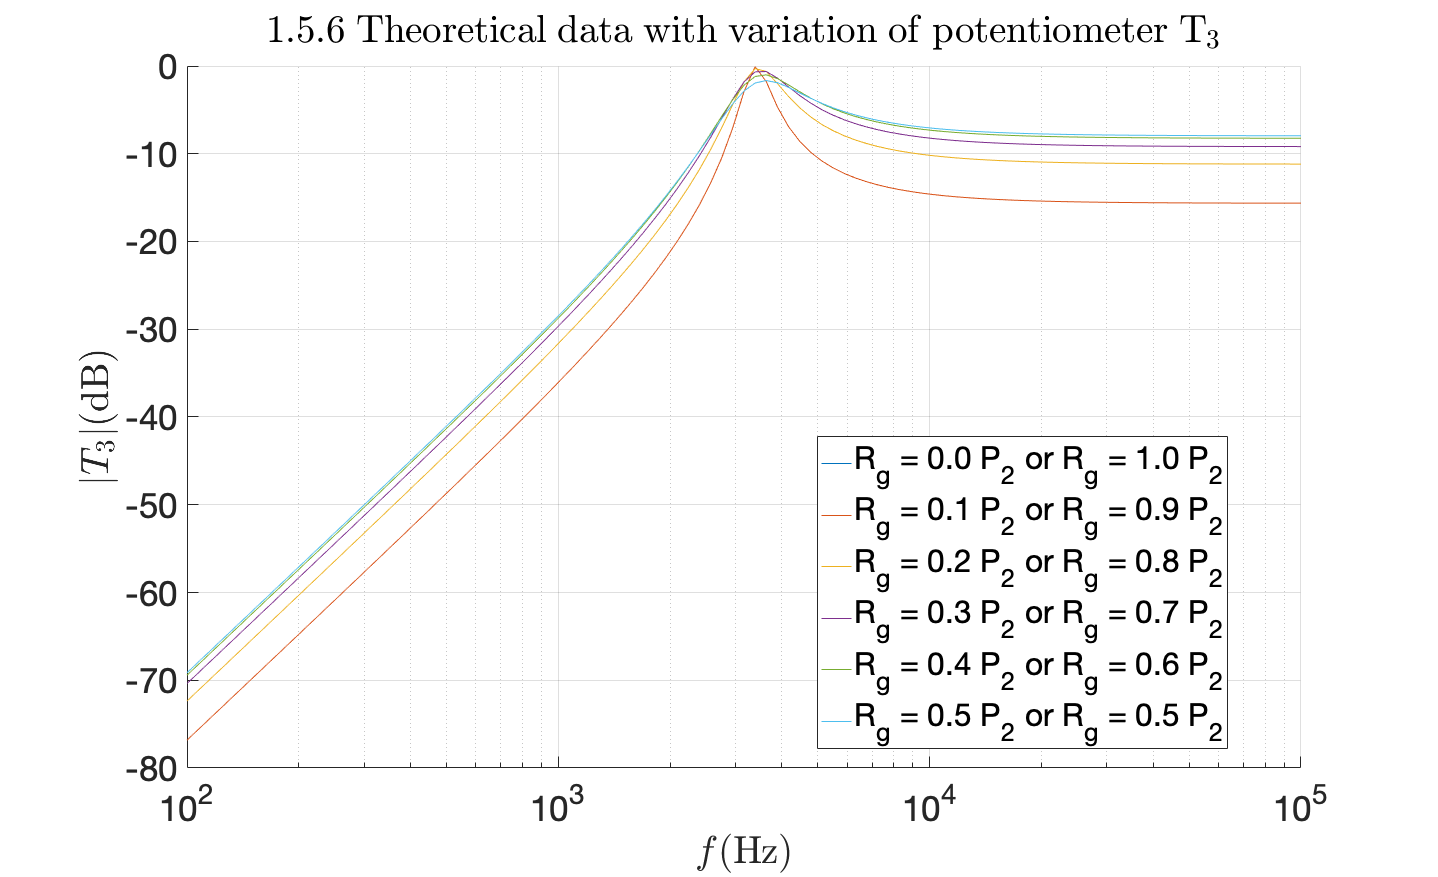

T_ = cell(3,length(Rg));
for i = 1:length(Rg)
    for filter = 1:3
        T_{filter,i} = zpk(K_(i)*s^2/(s^2+(omega_0/Q_(i))*s+omega_0^2));
    end
end

gainBode_ = zeros(3,length(f),length(Rg));
for i = 1:length(f)
    for filter = 1:3
        for j = 1:length(Rg)
            gainBode_(filter,i,j) = 20*log10(abs(freqresp(T_{filter,j},2*pi*f(i))));
        end
    end
end

for filter = 1:3
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    title(strcat('$1.5.6\; \mathrm{Theoretical\;data\;with\;variation\;of\;potentiometer}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
    lg = [];
    for i = 1:length(Rg)
        plot(f,gainBode_(filter,:,i));
        lg = [lg sprintf("R_g = %.01f P_2 or R_g = %.01f P_2",Rg(i)/P2,(1-Rg(i)/P2))];
    end
    legend(lg,'Location','best');
    set(gca,'xscale','log');
    ylabel(strcat(sprintf('$|T_%d|',filter),'\mathrm{(dB)}$'),'Interpreter','latex');
    xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
    saveas(gcf,sprintf('./Session1DATA/bodeTheoreticalPotentiometer%d.fig',filter));
    saveas(gcf,sprintf('./Session1DATA/bodeTheoreticalPotentiometer%d.png',filter));
    hold off; 
end

## Perguntas